## DATA & CONSTANTS

% OPEC Country data
reserves = [130000 45000 50000 35000 35000 45000 27500];
production_cap = [12000 4600 3700 3300 3000 4400 2700];
marginal_cost = [6 7 8 6 5 8 8];

%constants
net_days = 12;
endgame_bbl = 70;
interest_rate = 0.05;
demand_shock = 0;
supply_shock = 0;
marginal_cost_roo = mean(marginal_cost(1:end-1));
marginal_cost_weighted = sum(marginal_cost .* reserves) ./sum(reserves);
interest_table = net_days:-1:1;
interest_table = (1+interest_rate).^(interest_table);

# FUNDAMENTAL EQS

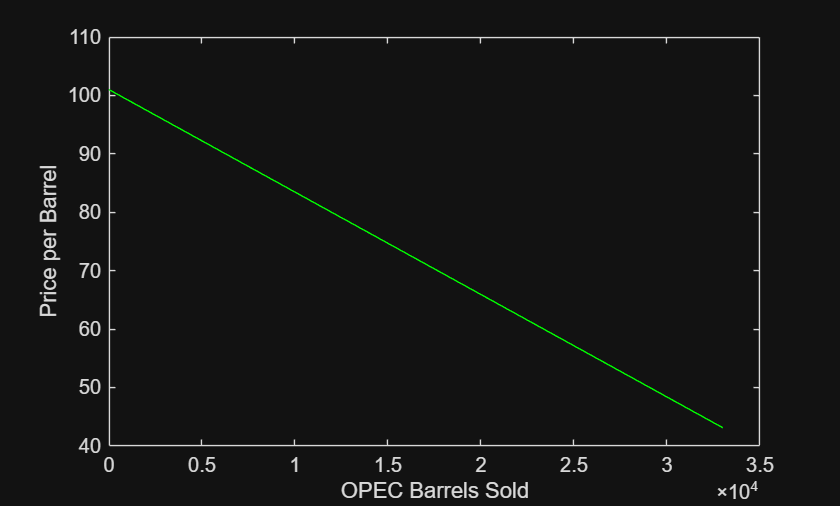

Q_d = @(P, demand_shock) 90000 - 450 * P + demand_shock;

Q_row = @(P, supply_shock) 32400 + 120*P + supply_shock;

P = @(Q_opec, demand_shock, supply_shock) 101 - (Q_opec./570) - ((demand_shock - supply_shock)./570);

R = @(Q_opec, demand_shock, supply_shock) Q_opec.*(101 - (Q_opec./570) - ((demand_shock - supply_shock)./570));

Q_domain = 0:1000:33500;
plot(Q_domain, P(Q_domain,demand_shock,supply_shock), 'g');
fig.Position(3:4) = [800, 600];
xlabel('OPEC Barrels Sold');
ylabel('Price per Barrel');

%profit equation for Nigeria
pi_7 = @(q_7, q_roo,demand_shock,supply_shock, marginal_cost) (P(q_7, q_roo,demand_shock,supply_shock) - marginal_cost(7)) .* q_7;
%profit equation for Rest of OPEC
pi_roo = @(q_7, q_roo,demand_shock,supply_shock) (P(q_7, q_roo,demand_shock,supply_shock,marginal_cost_roo) - marginal_cost_roo) .* q_roo;

## Boundary Examples

% max nigeria assumes no other OPEC production
nigeria_hegemony_profit = national_profit_calc([2700 2700 2700 2700 2700 2700 2700 2700 2700 2700], [96 96 96 96 96 96 96 96 96 96], marginal_cost(7), reserves(7), endgame_bbl, interest_rate);

## Q Space

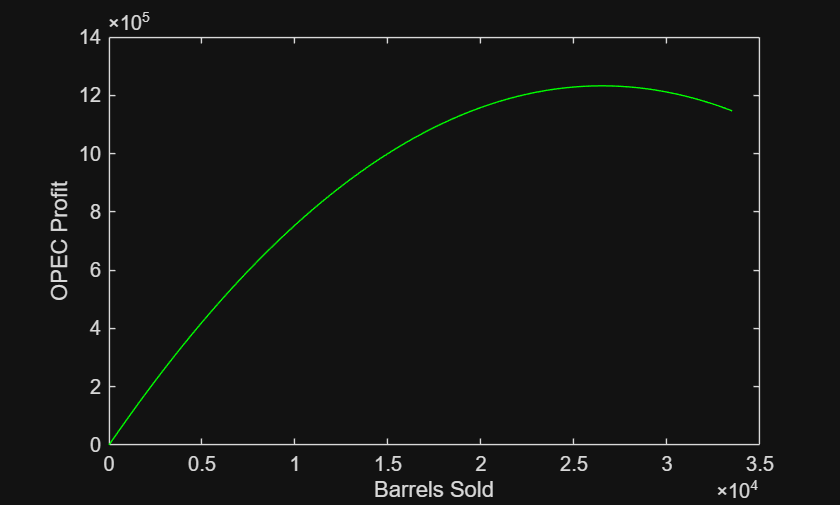

%assumes monopoly with infinite resource and no interest
Q_space = 0:500:sum(production_cap);
monopoly_price = price_per_day(P, Q_space, demand_shock, supply_shock);

monopoly_profit = Q_space .* (monopoly_price - marginal_cost(7));

%find price
monopoly_profit_max = max(monopoly_profit);
monopoly_profit_max_index = find(monopoly_profit == monopoly_profit_max);
monopoly_profit_max_bbl = Q_space(monopoly_profit_max_index);
monopoly_price = P(monopoly_profit_max_bbl, demand_shock, supply_shock);

plot(Q_space, monopoly_profit, 'g');
xlabel('Barrels Sold');
ylabel('OPEC Profit');

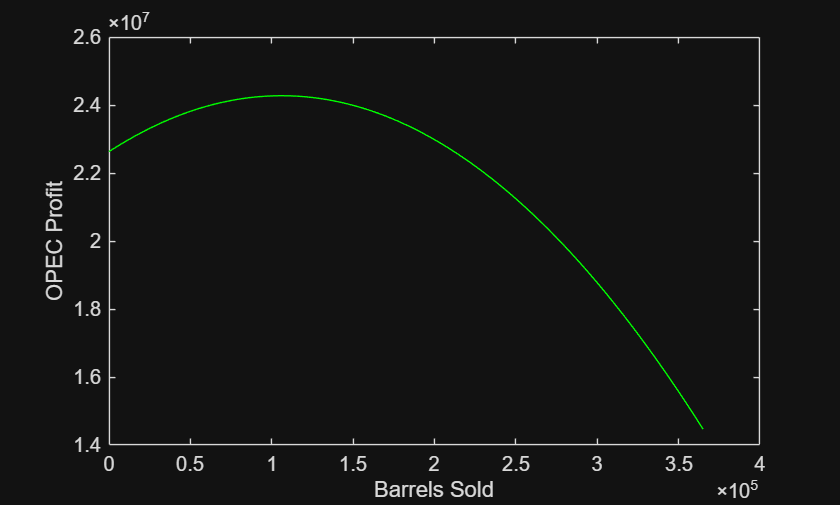


%assumes monopoly with finite resource and endgame
%assumes no interest
Q_space_finite = 0:5000:sum(reserves);
Q_reserve_finite = max(Q_space_finite);
monopoly_price_finite = price_per_day(P, Q_space_finite./net_days, demand_shock, supply_shock);
monopoly_profit_production = Q_space_finite .* (monopoly_price_finite - marginal_cost(7));
monopoly_profit_leftover = (Q_reserve_finite - Q_space_finite) * (endgame_bbl - marginal_cost(7));
monopoly_profit_finite = monopoly_profit_production + monopoly_profit_leftover;
plot(Q_space_finite, monopoly_profit_finite, 'g');
xlabel('Barrels Sold');
ylabel('OPEC Profit');

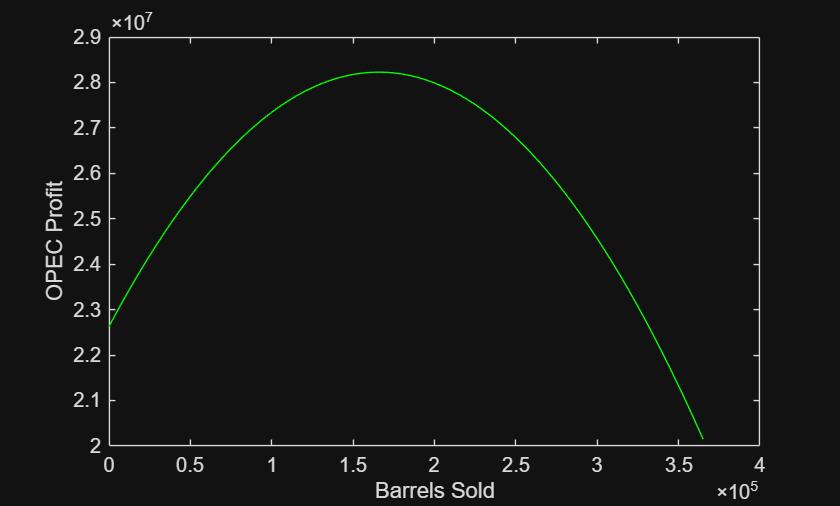

monopoly_profit_finite_max = max(monopoly_profit_finite);
monopoly_profit_finite_max_index = find(monopoly_profit_finite == monopoly_profit_finite_max);
monopoly_profit_finite_max_bbl = Q_space_finite(monopoly_profit_finite_max_index);

%find collusion ideal outcome from finite
collusion_from_production_finite = (monopoly_profit_finite_max_bbl/net_days) .* (production_cap/sum(production_cap));
collusion_from_reserves_finite = (monopoly_profit_finite_max_bbl/net_days) .* (reserves/sum(reserves));
price_from_production_collusion_finite = P(sum(collusion_from_reserves_finite), demand_shock, supply_shock);
price_from_reserve_collusion_finite = P(sum(collusion_from_reserves_finite), demand_shock, supply_shock);

%assumes monopoly with interest
Q_space_interest = 0:5000:sum(reserves);
Q_reserve_interest = max(Q_space_interest);
monopoly_price_interest = price_per_day(P, Q_space_interest./net_days, demand_shock, supply_shock);
%monopoly_profit_production_interest = Q_space_interest .* (monopoly_price_interest - marginal_cost(7));
monopoly_profit_production_interest = ones(1, length(monopoly_price_interest));
%calc profit per day and find sum
for i = 1:length(monopoly_price_interest)
    gross_profit = Q_space_interest(i) .* (monopoly_price_interest(i) - marginal_cost(7));
    divided_profit = gross_profit ./ net_days;
    daily_profit = divided_profit .* ones(1,net_days);
    monopoly_profit_production_interest(i) = add_interest(daily_profit,interest_rate);
end
monopoly_profit_leftover_interest = (Q_reserve_interest - Q_space_interest) * (endgame_bbl - marginal_cost(7));
monopoly_profit_interest = monopoly_profit_production_interest + monopoly_profit_leftover_interest;
plot(Q_space_interest, monopoly_profit_interest, 'g');
xlabel('Barrels Sold');
ylabel('OPEC Profit');

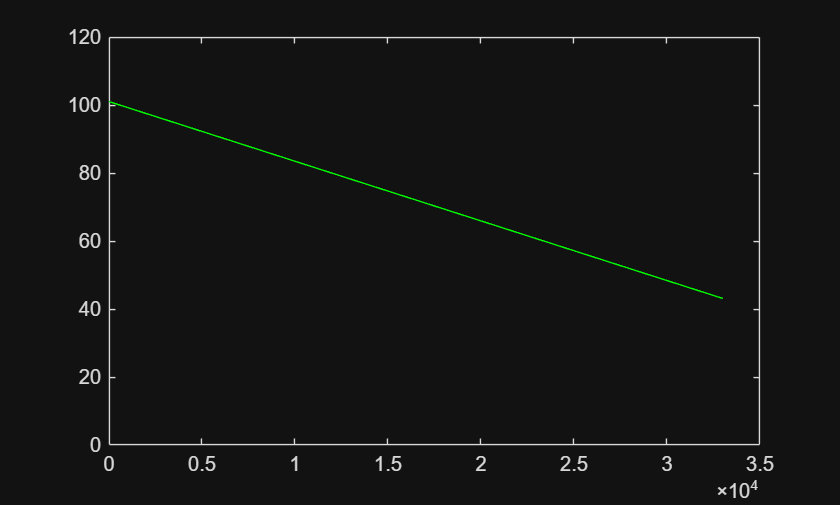

%find max profit
monopoly_profit_interest_max = max(monopoly_profit_interest);
monopoly_profit_interest_max_index = find(monopoly_profit_interest == monopoly_profit_interest_max);
monopoly_profit_interest_max_bbl = Q_space_finite(monopoly_profit_interest_max_index);

%find collusion ideal outcome from interest
collusion_from_production_interest = (monopoly_profit_interest_max_bbl/net_days) .* (production_cap/sum(production_cap));
collusion_from_reserves_interest = (monopoly_profit_interest_max_bbl/net_days) .* (reserves/sum(reserves));
price_from_production_collusion_interest = P(sum(collusion_from_reserves_interest), demand_shock, supply_shock);
price_from_reserve_collusion_interest = P(sum(collusion_from_reserves_interest), demand_shock, supply_shock);

%find Cournot solution
Q_space_7 = 0:1000:production_cap(7);
Q_space_roo = 0:1000:(sum(production_cap) - production_cap(7));

%graph reply function
plot(Q_domain, P(Q_domain,demand_shock,supply_shock), 'g');
hold on;
plot(Q_domain, marginal_cost(7), 'r');
plot(Q_domain, marginal_cost_roo, 'm');

## COLLUSION CASE

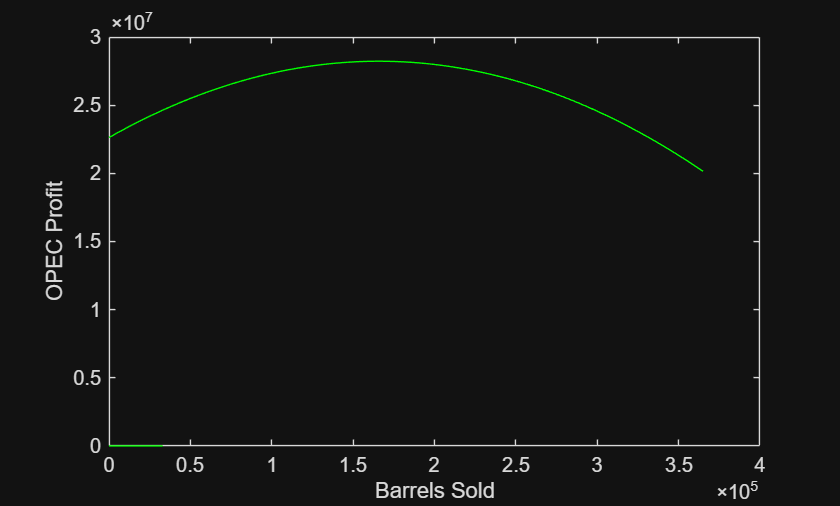

Q_collusion = 0:1000:sum(reserves);
collusion_sale_revenue = R(Q_collusion,demand_shock, supply_shock);
collusion_sale_profit = collusion_sale_revenue - (Q_collusion .* marginal_cost_weighted);
collusion_sale_profit_vested = collusion_sale_profit .* interest_table(1);
collusion_leftover_profit = 0;

plot(Q_space_interest, monopoly_profit_interest, 'g');
xlabel('Barrels Sold');
ylabel('OPEC Profit');

## SWARM OPTIMIZATION

for i = 1:100
    daily = 8000 .* ones(1, net_days);
    overall_profit = overall_profit_calc(daily, marginal_cost_weighted, sum(reserves), endgame_bbl, interest_rate, net_days);
end